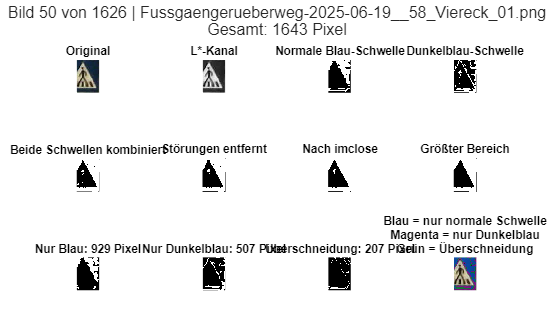

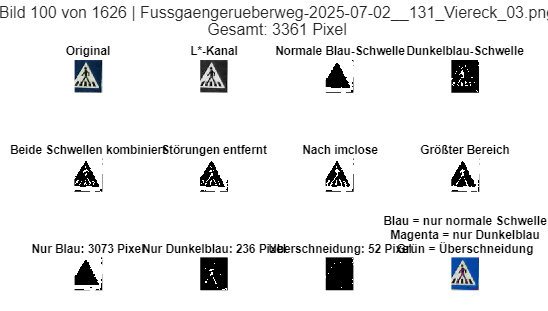

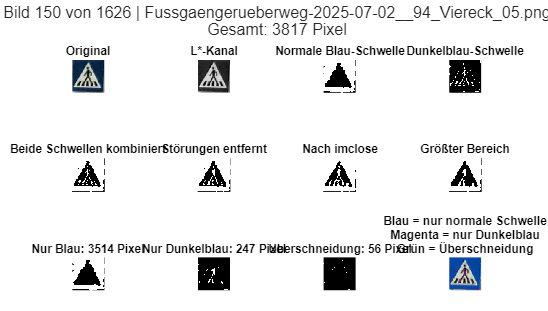

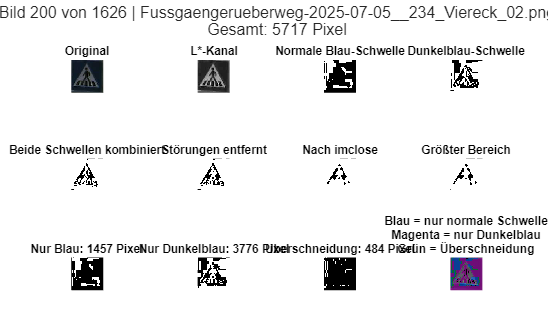

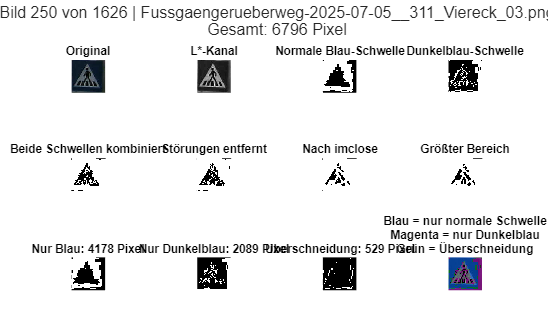

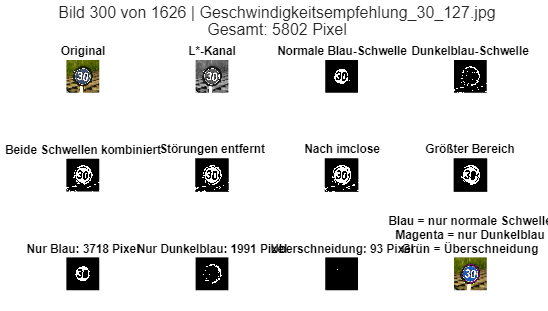

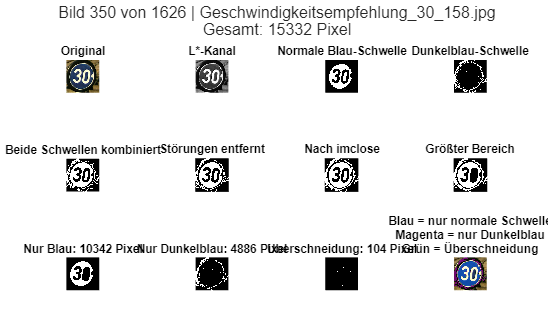

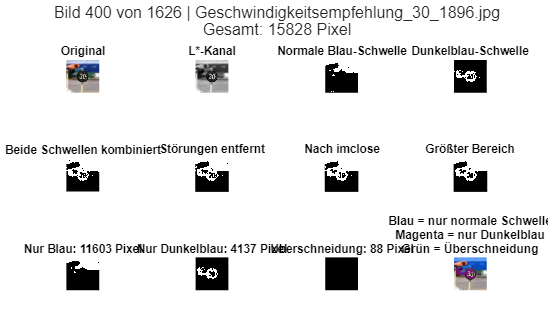

%% =========================================================
% Analyse der normalen Blau- und Dunkelblau-Schwelle
%
% Untersucht werden ausschließlich bereits ausgeschnittene
% blaue Verkehrszeichen.
%
% Die erkannten Pixel werden in vier Gruppen eingeteilt:
%
%   1. Nur normale Blau-Schwelle
%   2. Nur Dunkelblau-Schwelle
%   3. Von beiden Schwellen erkannt
%   4. Gesamtheit aller erkannten Pixel
%
% Bei jedem 50. Bild werden die Verarbeitungsschritte angezeigt.
% Zusätzlich werden LAB-Verteilungen und Perzentile berechnet.
% ==========================================================

clear;
clc;
close all;


%% 1. Ordner der ausgeschnittenen blauen Schilder

blueFolder = ...
    "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\8_blaueSchilder";


%% 2. Ausgabeordner

outputFolder = fullfile( ...
    fileparts(blueFolder), ...
    "LAB_Analyse_Blau");

if ~exist(outputFolder, "dir")
    mkdir(outputFolder);
end


%% 3. Aktuelle LAB-Schwellen

% Reihenfolge:
% [L_min, L_max, a_min, a_max, b_min, b_max]

blueThreshold = [
       0, 100, ...
     -30,  25, ...
    -128,   -8
];

darkBlueThreshold = [
      5, 30, ...
    -10,  5, ...
    -10, 12
];


%% 4. Allgemeine Einstellungen

% Perzentile zur Beschreibung der Pixelverteilungen
percentileLow  = 2;
percentileHigh = 98;

% Höchstens so viele Pixel je Gruppe und Bild übernehmen.
% Dadurch werden große Schilder nicht übergewichtet.
maxPixelsPerImagePerGroup = 1000;

% Kleine zusammenhängende Farbflächen entfernen
minObjectArea = 10;

% Radius für das morphologische Schließen
closeRadius = 2;

% Nur jedes 50. Bild darstellen
displayEvery = 50;

% Maximale Pixelzahl je Gruppe in den Diagrammen
maxPlotPixels = 50000;

% Reproduzierbare Zufallsauswahl
rng(1, "twister");


%% 5. Bilder erfassen

imds = imageDatastore( ...
    blueFolder, ...
    "IncludeSubfolders", true);

numberOfImages = numel(imds.Files);

if numberOfImages == 0
    error("Im Ordner wurden keine Bilder gefunden.");
end


%% 6. Speicher für LAB-Werte vorbereiten

% Nur normale Blau-Schwelle
blueOnlyCells = cell(numberOfImages, 1);

% Nur Dunkelblau-Schwelle
darkOnlyCells = cell(numberOfImages, 1);

% Von beiden Schwellen erkannt
overlapCells = cell(numberOfImages, 1);

% Gesamtheit der erkannten Pixel
combinedCells = cell(numberOfImages, 1);


%% 7. Speicher für Auswertung pro Bild

fileNames = cell(numberOfImages, 1);

blueOnlyPixelCount = zeros(numberOfImages, 1);
darkOnlyPixelCount = zeros(numberOfImages, 1);
overlapPixelCount = zeros(numberOfImages, 1);
combinedPixelCount = zeros(numberOfImages, 1);

usedImage = false(numberOfImages, 1);


%% 8. Grenzwerte der normalen Blau-Schwelle auslesen

blueLmin = blueThreshold(1);
blueLmax = blueThreshold(2);

blueAmin = blueThreshold(3);
blueAmax = blueThreshold(4);

blueBmin = blueThreshold(5);
blueBmax = blueThreshold(6);


%% 9. Grenzwerte der Dunkelblau-Schwelle auslesen

darkLmin = darkBlueThreshold(1);
darkLmax = darkBlueThreshold(2);

darkAmin = darkBlueThreshold(3);
darkAmax = darkBlueThreshold(4);

darkBmin = darkBlueThreshold(5);
darkBmax = darkBlueThreshold(6);


%% 10. Alle Bilder durchlaufen

for i = 1:numberOfImages

    %% Bild einlesen

    I = imread(imds.Files{i});

    % Graubilder in RGB umwandeln
    if ndims(I) == 2 || size(I, 3) == 1
        I = repmat(I, 1, 1, 3);
    end

    % Alphakanal entfernen
    if size(I, 3) > 3
        I = I(:,:,1:3);
    end


    %% Dateinamen speichern

    [~, currentName, currentExtension] = ...
        fileparts(imds.Files{i});

    fileNames{i} = [
        currentName, ...
        currentExtension
    ];


    %% RGB nach LAB umwandeln

    labImage = rgb2lab(I);

    L = labImage(:,:,1);
    A = labImage(:,:,2);
    B = labImage(:,:,3);


    %% Normale Blau-Schwelle anwenden

    blueRawMask = ...
        L >= blueLmin & ...
        L <= blueLmax & ...
        A >= blueAmin & ...
        A <= blueAmax & ...
        B >= blueBmin & ...
        B <= blueBmax;


    %% Dunkelblau-Schwelle anwenden

    darkRawMask = ...
        L >= darkLmin & ...
        L <= darkLmax & ...
        A >= darkAmin & ...
        A <= darkAmax & ...
        B >= darkBmin & ...
        B <= darkBmax;


    %% Beide Masken zusammenführen

    combinedRawMask = ...
        blueRawMask | darkRawMask;


    %% Kleine Störflächen entfernen

    cleanCombinedMask = bwareaopen( ...
        combinedRawMask, ...
        minObjectArea);


    %% Kleine Lücken verbinden

    structuralElement = strel( ...
        "disk", ...
        closeRadius, ...
        0);

    connectedCombinedMask = imclose( ...
        cleanCombinedMask, ...
        structuralElement);


    %% Größten zusammenhängenden Bereich auswählen

    % Da die Bilder bereits auf ein blaues Schild zugeschnitten
    % wurden, wird angenommen, dass der größte erkannte Bereich
    % zur Schildfläche gehört.

    if any(connectedCombinedMask(:))

        largestRegion = bwareafilt( ...
            connectedCombinedMask, ...
            1);

    else

        largestRegion = false( ...
            size(connectedCombinedMask));

    end


    %% Nur ursprünglich erkannte Farbpixel übernehmen

    finalBlueMask = ...
        blueRawMask & largestRegion;

    finalDarkMask = ...
        darkRawMask & largestRegion;


    %% Pixelgruppen bilden

    % Nur durch die normale Blau-Schwelle erkannt
    blueOnlyMask = ...
        finalBlueMask & ~finalDarkMask;

    % Nur durch die Dunkelblau-Schwelle erkannt
    darkOnlyMask = ...
        finalDarkMask & ~finalBlueMask;

    % Von beiden Schwellen erkannt
    overlapMask = ...
        finalBlueMask & finalDarkMask;

    % Gesamtheit aller erkannten Pixel
    finalCombinedMask = ...
        finalBlueMask | finalDarkMask;


    %% Pixelzahlen des Bildes erfassen

    blueOnlyPixelCount(i) = ...
        nnz(blueOnlyMask);

    darkOnlyPixelCount(i) = ...
        nnz(darkOnlyMask);

    overlapPixelCount(i) = ...
        nnz(overlapMask);

    combinedPixelCount(i) = ...
        nnz(finalCombinedMask);

    usedImage(i) = ...
        combinedPixelCount(i) > 0;


    %% LAB-Werte der vier Gruppen auslesen

    currentBlueOnlyValues = [
        L(blueOnlyMask), ...
        A(blueOnlyMask), ...
        B(blueOnlyMask)
    ];

    currentDarkOnlyValues = [
        L(darkOnlyMask), ...
        A(darkOnlyMask), ...
        B(darkOnlyMask)
    ];

    currentOverlapValues = [
        L(overlapMask), ...
        A(overlapMask), ...
        B(overlapMask)
    ];

    currentCombinedValues = [
        L(finalCombinedMask), ...
        A(finalCombinedMask), ...
        B(finalCombinedMask)
    ];


    %% Pixelzahl pro Bild und Gruppe begrenzen

    currentBlueOnlyValues = limitPixelCount( ...
        currentBlueOnlyValues, ...
        maxPixelsPerImagePerGroup);

    currentDarkOnlyValues = limitPixelCount( ...
        currentDarkOnlyValues, ...
        maxPixelsPerImagePerGroup);

    currentOverlapValues = limitPixelCount( ...
        currentOverlapValues, ...
        maxPixelsPerImagePerGroup);

    currentCombinedValues = limitPixelCount( ...
        currentCombinedValues, ...
        maxPixelsPerImagePerGroup);


    %% LAB-Werte speichern

    blueOnlyCells{i} = ...
        currentBlueOnlyValues;

    darkOnlyCells{i} = ...
        currentDarkOnlyValues;

    overlapCells{i} = ...
        currentOverlapValues;

    combinedCells{i} = ...
        currentCombinedValues;


    %% Nur jedes 50. Bild darstellen

    if displayEvery > 0 && ...
            mod(i, displayEvery) == 0

        figure( ...
            "Name", ...
            "Blauanalyse | Bild " + i + ...
            " von " + numberOfImages, ...
            "NumberTitle", "off", ...
            "Position", [50, 50, 1500, 850]);

        tiledlayout( ...
            3, ...
            4, ...
            "TileSpacing", "compact", ...
            "Padding", "compact");


        % 1. Original
        nexttile;
        imshow(I);
        title("Original");


        % 2. L*-Kanal
        nexttile;
        imshow(L, []);
        title("L*-Kanal");


        % 3. Normale Blau-Schwelle
        nexttile;
        imshow(blueRawMask);
        title("Normale Blau-Schwelle");


        % 4. Dunkelblau-Schwelle
        nexttile;
        imshow(darkRawMask);
        title("Dunkelblau-Schwelle");


        % 5. Gemeinsame Rohmaske
        nexttile;
        imshow(combinedRawMask);
        title("Beide Schwellen kombiniert");


        % 6. Kleine Störungen entfernt
        nexttile;
        imshow(cleanCombinedMask);
        title("Störungen entfernt");


        % 7. Nach imclose
        nexttile;
        imshow(connectedCombinedMask);
        title("Nach imclose");


        % 8. Größter Bereich
        nexttile;
        imshow(largestRegion);
        title("Größter Bereich");


        % 9. Nur normales Blau
        nexttile;
        imshow(blueOnlyMask);
        title(sprintf( ...
            "Nur Blau: %d Pixel", ...
            blueOnlyPixelCount(i)));


        % 10. Nur Dunkelblau
        nexttile;
        imshow(darkOnlyMask);
        title(sprintf( ...
            "Nur Dunkelblau: %d Pixel", ...
            darkOnlyPixelCount(i)));


        % 11. Überschneidung
        nexttile;
        imshow(overlapMask);
        title(sprintf( ...
            "Überschneidung: %d Pixel", ...
            overlapPixelCount(i)));


        % 12. Farbige Überlagerung
        nexttile;

        groupLabels = zeros( ...
            size(finalCombinedMask), ...
            "uint8");

        groupLabels(blueOnlyMask) = 1;
        groupLabels(darkOnlyMask) = 2;
        groupLabels(overlapMask) = 3;

        overlayImage = labeloverlay( ...
            I, ...
            groupLabels, ...
            "Colormap", ...
            [ ...
                0.00, 0.40, 1.00; ...
                0.80, 0.00, 0.80; ...
                0.00, 0.75, 0.20 ...
            ], ...
            "Transparency", 0.50);

        imshow(overlayImage);

        title({ ...
            "Blau = nur normale Schwelle", ...
            "Magenta = nur Dunkelblau", ...
            "Grün = Überschneidung" ...
        }, ...
        "FontSize", 9);


        sgtitle( ...
            { ...
                sprintf( ...
                    "Bild %d von %d | %s", ...
                    i, ...
                    numberOfImages, ...
                    fileNames{i}), ...
                sprintf( ...
                    "Gesamt: %d Pixel", ...
                    combinedPixelCount(i)) ...
            }, ...
            "Interpreter", "none", ...
            "FontSize", 12);

    end

end



%% 11. LAB-Werte aller Bilder zusammenführen

labBlueOnly = combinePixelCells( ...
    blueOnlyCells);

labDarkOnly = combinePixelCells( ...
    darkOnlyCells);

labOverlap = combinePixelCells( ...
    overlapCells);

labCombined = combinePixelCells( ...
    combinedCells);


%% 12. Perzentilbereiche berechnen

blueOnlySuggestedThreshold = ...
    calculateThresholdSafe( ...
        labBlueOnly, ...
        percentileLow, ...
        percentileHigh);

darkOnlySuggestedThreshold = ...
    calculateThresholdSafe( ...
        labDarkOnly, ...
        percentileLow, ...
        percentileHigh);

overlapSuggestedThreshold = ...
    calculateThresholdSafe( ...
        labOverlap, ...
        percentileLow, ...
        percentileHigh);

combinedSuggestedThreshold = ...
    calculateThresholdSafe( ...
        labCombined, ...
        percentileLow, ...
        percentileHigh);


%% 13. Ergebnisse ausgeben

fprintf("\n");
fprintf("============================================\n");

fprintf("Blauanalyse abgeschlossen\n");

Blauanalyse abgeschlossen


fprintf("============================================\n\n");


fprintf("Bilder insgesamt:        %d\n", ...
    numberOfImages);

Bilder insgesamt:        1626



fprintf("Bilder mit erkannten Pixeln: %d\n\n", ...
    sum(usedImage));

Bilder mit erkannten Pixeln: 1626




fprintf("Pixel nur normale Blau-Schwelle: %d\n", ...
    size(labBlueOnly, 1));

Pixel nur normale Blau-Schwelle: 1346723



fprintf("Pixel nur Dunkelblau-Schwelle:   %d\n", ...
    size(labDarkOnly, 1));

Pixel nur Dunkelblau-Schwelle:   1384730



fprintf("Pixel in der Überschneidung:     %d\n", ...
    size(labOverlap, 1));

Pixel in der Überschneidung:     369000



fprintf("Kombinierte Pixel:               %d\n\n", ...
    size(labCombined, 1));

Kombinierte Pixel:               1617533





fprintf("Aktuelle normale Blau-Schwelle:\n");

Aktuelle normale Blau-Schwelle:


fprintf( ...
    "blue_threshold = (%d, %d, %d, %d, %d, %d)\n\n", ...
    blueThreshold);

blue_threshold = (0, 100, -30, 25, -128, -8)





fprintf("Aktuelle Dunkelblau-Schwelle:\n");

Aktuelle Dunkelblau-Schwelle:


fprintf( ...
    "dark_blue_threshold = (%d, %d, %d, %d, %d, %d)\n\n", ...
    darkBlueThreshold);

dark_blue_threshold = (5, 30, -10, 5, -10, 12)





fprintf("2.- bis 98. Perzentil der Pixel,\n");

2.- bis 98. Perzentil der Pixel,


fprintf("die ausschließlich die normale Blau-Schwelle benötigen:\n");

die ausschließlich die normale Blau-Schwelle benötigen:



printThreshold( ...
    "blue_only_suggested", ...
    blueOnlySuggestedThreshold);

blue_only_suggested = (4, 82, -11, 19, -44, -9)




fprintf("\n2.- bis 98. Perzentil der Pixel,\n");


2.- bis 98. Perzentil der Pixel,


fprintf("die ausschließlich die Dunkelblau-Schwelle erkennt:\n");

die ausschließlich die Dunkelblau-Schwelle erkennt:



printThreshold( ...
    "dark_only_suggested", ...
    darkOnlySuggestedThreshold);

dark_only_suggested = (5, 29, -9, 3, -8, 11)




fprintf("\n2.- bis 98. Perzentil der Überschneidung:\n");


2.- bis 98. Perzentil der Überschneidung:



printThreshold( ...
    "overlap_suggested", ...
    overlapSuggestedThreshold);

overlap_suggested = (5, 29, -9, 3, -10, -8)




fprintf("\n2.- bis 98. Perzentil aller erkannten Pixel:\n");


2.- bis 98. Perzentil aller erkannten Pixel:



printThreshold( ...
    "combined_suggested", ...
    combinedSuggestedThreshold);

combined_suggested = (5, 79, -10, 18, -42, 10)


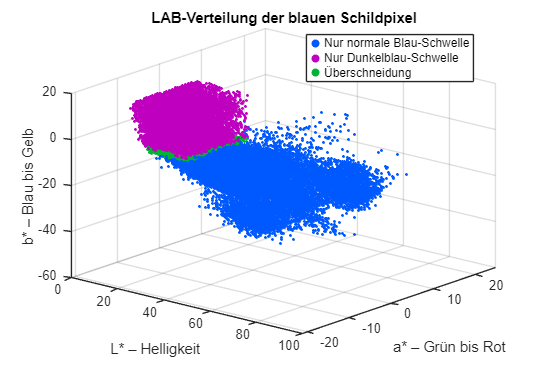



%% 14. Auswertung pro Bild als CSV speichern

imageResultTable = table( ...
    fileNames, ...
    blueOnlyPixelCount, ...
    darkOnlyPixelCount, ...
    overlapPixelCount, ...
    combinedPixelCount, ...
    usedImage, ...
    'VariableNames', ...
    { ...
        'Bildname', ...
        'PixelNurBlau', ...
        'PixelNurDunkelblau', ...
        'PixelUeberschneidung', ...
        'PixelGesamt', ...
        'BildVerwendet' ...
    });


imageOutputFile = fullfile( ...
    outputFolder, ...
    "Blauanalyse_pro_Bild.csv");

writetable( ...
    imageResultTable, ...
    imageOutputFile);


%% 15. Zusammenfassung der Schwellen als CSV

groupNames = {
    "Nur normale Blau-Schwelle";
    "Nur Dunkelblau-Schwelle";
    "Ueberschneidung";
    "Gesamtheit"
};

thresholdMatrix = [
    blueOnlySuggestedThreshold;
    darkOnlySuggestedThreshold;
    overlapSuggestedThreshold;
    combinedSuggestedThreshold
];

pixelNumbers = [
    size(labBlueOnly, 1);
    size(labDarkOnly, 1);
    size(labOverlap, 1);
    size(labCombined, 1)
];

thresholdResultTable = table( ...
    groupNames, ...
    pixelNumbers, ...
    thresholdMatrix(:,1), ...
    thresholdMatrix(:,2), ...
    thresholdMatrix(:,3), ...
    thresholdMatrix(:,4), ...
    thresholdMatrix(:,5), ...
    thresholdMatrix(:,6), ...
    'VariableNames', ...
    { ...
        'Pixelgruppe', ...
        'AnzahlPixel', ...
        'L_min', ...
        'L_max', ...
        'A_min', ...
        'A_max', ...
        'B_min', ...
        'B_max' ...
    });

thresholdOutputFile = fullfile( ...
    outputFolder, ...
    "Blauanalyse_Schwellenbereiche.csv");

writetable( ...
    thresholdResultTable, ...
    thresholdOutputFile);


%% 16. Teilmengen für Diagramme auswählen

labBlueOnlyPlot = selectPlotPixels( ...
    labBlueOnly, ...
    maxPlotPixels);

labDarkOnlyPlot = selectPlotPixels( ...
    labDarkOnly, ...
    maxPlotPixels);

labOverlapPlot = selectPlotPixels( ...
    labOverlap, ...
    maxPlotPixels);


%% 17. Dreidimensionale LAB-Verteilung

figure( ...
    "Name", ...
    "3D-LAB-Verteilung Blau", ...
    "NumberTitle", "off", ...
    "Position", [100, 100, 1100, 750]);

hold on;

scatter3( ...
    labBlueOnlyPlot(:,1), ...
    labBlueOnlyPlot(:,2), ...
    labBlueOnlyPlot(:,3), ...
    5, ...
    [0.00, 0.35, 1.00], ...
    "filled");

scatter3( ...
    labDarkOnlyPlot(:,1), ...
    labDarkOnlyPlot(:,2), ...
    labDarkOnlyPlot(:,3), ...
    5, ...
    [0.75, 0.00, 0.75], ...
    "filled");

scatter3( ...
    labOverlapPlot(:,1), ...
    labOverlapPlot(:,2), ...
    labOverlapPlot(:,3), ...
    5, ...
    [0.00, 0.70, 0.20], ...
    "filled");

xlabel("L* – Helligkeit");
ylabel("a* – Grün bis Rot");
zlabel("b* – Blau bis Gelb");

title("LAB-Verteilung der blauen Schildpixel");

legend( ...
    "Nur normale Blau-Schwelle", ...
    "Nur Dunkelblau-Schwelle", ...
    "Überschneidung", ...
    "Location", "best");

grid on;
view(40, 25);
hold off;



%% 18. Verteilung im a*-b*-Raum

figure( ...
    "Name", ...
    "a-b-Verteilung Blau", ...
    "NumberTitle", "off", ...
    "Position", [100, 100, 1100, 750]);

hold on;

scatter( ...
    labBlueOnlyPlot(:,2), ...
    labBlueOnlyPlot(:,3), ...
    5, ...
    [0.00, 0.35, 1.00], ...
    "filled");

scatter( ...
    labDarkOnlyPlot(:,2), ...
    labDarkOnlyPlot(:,3), ...
    5, ...
    [0.75, 0.00, 0.75], ...
    "filled");

scatter( ...
    labOverlapPlot(:,2), ...
    labOverlapPlot(:,3), ...
    5, ...
    [0.00, 0.70, 0.20], ...
    "filled");


% Aktuelle normale Blau-Schwelle
rectangle( ...
    "Position", ...
    [ ...
        blueThreshold(3), ...
        blueThreshold(5), ...
        blueThreshold(4) - blueThreshold(3), ...
        blueThreshold(6) - blueThreshold(5) ...
    ], ...
    "EdgeColor", ...
    [0.00, 0.20, 0.80], ...
    "LineWidth", 2, ...
    "LineStyle", "-");


% Aktuelle Dunkelblau-Schwelle
rectangle( ...
    "Position", ...
    [ ...
        darkBlueThreshold(3), ...
        darkBlueThreshold(5), ...
        darkBlueThreshold(4) - darkBlueThreshold(3), ...
        darkBlueThreshold(6) - darkBlueThreshold(5) ...
    ], ...
    "EdgeColor", ...
    [0.65, 0.00, 0.65], ...
    "LineWidth", 2, ...
    "LineStyle", "-");


% Vorschlag auf Grundlage der Nur-Blau-Pixel
if all(isfinite(blueOnlySuggestedThreshold))

    rectangle( ...
        "Position", ...
        [ ...
            blueOnlySuggestedThreshold(3), ...
            blueOnlySuggestedThreshold(5), ...
            blueOnlySuggestedThreshold(4) - ...
                blueOnlySuggestedThreshold(3), ...
            blueOnlySuggestedThreshold(6) - ...
                blueOnlySuggestedThreshold(5) ...
        ], ...
        "EdgeColor", ...
        [0.00, 0.65, 0.90], ...
        "LineWidth", 2.5, ...
        "LineStyle", "--");

end

xlabel("a* – Grün bis Rot");
ylabel("b* – Blau bis Gelb");

title({ ...
    "Verteilung im a*-b*-Raum", ...
    "Gestricheltes Rechteck = Perzentilbereich der Nur-Blau-Pixel" ...
});

legend( ...
    "Nur normale Blau-Schwelle", ...
    "Nur Dunkelblau-Schwelle", ...
    "Überschneidung", ...
    "Aktuelle Blau-Schwelle", ...
    "Aktuelle Dunkelblau-Schwelle", ...
    "Vorschlag normale Blau-Schwelle", ...
    "Location", "best");

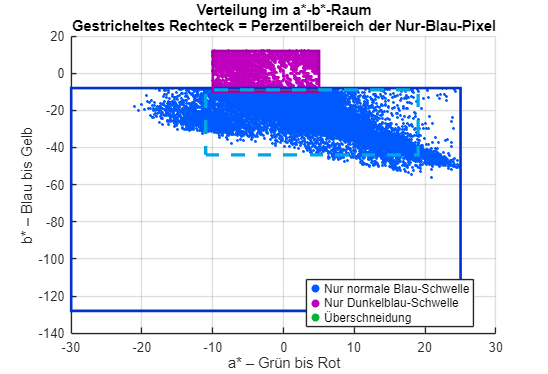


grid on;
hold off;

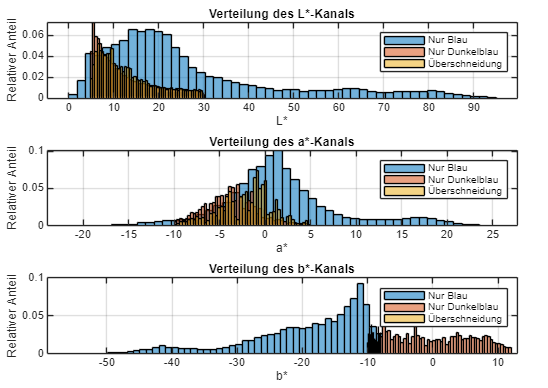



%% 19. Histogramme der einzelnen LAB-Kanäle

figure( ...
    "Name", ...
    "LAB-Histogramme Blau", ...
    "NumberTitle", "off", ...
    "Position", [100, 50, 1200, 850]);

tiledlayout( ...
    3, ...
    1, ...
    "TileSpacing", "compact", ...
    "Padding", "compact");


%% L*-Histogramm

nexttile;

histogram( ...
    labBlueOnlyPlot(:,1), ...
    50, ...
    "Normalization", "probability", ...
    "FaceAlpha", 0.55);

hold on;

histogram( ...
    labDarkOnlyPlot(:,1), ...
    50, ...
    "Normalization", "probability", ...
    "FaceAlpha", 0.55);

histogram( ...
    labOverlapPlot(:,1), ...
    50, ...
    "Normalization", "probability", ...
    "FaceAlpha", 0.55);

xlabel("L*");
ylabel("Relativer Anteil");
title("Verteilung des L*-Kanals");

legend( ...
    "Nur Blau", ...
    "Nur Dunkelblau", ...
    "Überschneidung");

grid on;
hold off;


%% a*-Histogramm

nexttile;

histogram( ...
    labBlueOnlyPlot(:,2), ...
    50, ...
    "Normalization", "probability", ...
    "FaceAlpha", 0.55);

hold on;

histogram( ...
    labDarkOnlyPlot(:,2), ...
    50, ...
    "Normalization", "probability", ...
    "FaceAlpha", 0.55);

histogram( ...
    labOverlapPlot(:,2), ...
    50, ...
    "Normalization", "probability", ...
    "FaceAlpha", 0.55);

xlabel("a*");
ylabel("Relativer Anteil");
title("Verteilung des a*-Kanals");

legend( ...
    "Nur Blau", ...
    "Nur Dunkelblau", ...
    "Überschneidung");

grid on;
hold off;


%% b*-Histogramm

nexttile;

histogram( ...
    labBlueOnlyPlot(:,3), ...
    50, ...
    "Normalization", "probability", ...
    "FaceAlpha", 0.55);

hold on;

histogram( ...
    labDarkOnlyPlot(:,3), ...
    50, ...
    "Normalization", "probability", ...
    "FaceAlpha", 0.55);

histogram( ...
    labOverlapPlot(:,3), ...
    50, ...
    "Normalization", "probability", ...
    "FaceAlpha", 0.55);

xlabel("b*");
ylabel("Relativer Anteil");
title("Verteilung des b*-Kanals");

legend( ...
    "Nur Blau", ...
    "Nur Dunkelblau", ...
    "Überschneidung");

grid on;
hold off;



%% 20. Speicherorte ausgeben

fprintf("\n");
fprintf("Auswertung pro Bild:\n%s\n\n", ...
    imageOutputFile);

Auswertung pro Bild:
C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\LAB_Analyse_Blau\Blauanalyse_pro_Bild.csv




fprintf("Zusammenfassung der Schwellenbereiche:\n%s\n", ...
    thresholdOutputFile);

Zusammenfassung der Schwellenbereiche:
C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\LAB_Analyse_Blau\Blauanalyse_Schwellenbereiche.csv




%% =========================================================
% Funktion: Pixelanzahl begrenzen
% ==========================================================

function limitedValues = limitPixelCount( ...
    values, ...
    maximumNumber)

    if isempty(values)

        limitedValues = zeros(0, 3);
        return;

    end

    if size(values, 1) <= maximumNumber

        limitedValues = values;

    else

        selectedIndices = randperm( ...
            size(values, 1), ...
            maximumNumber);

        limitedValues = values( ...
            selectedIndices, ...
            :);

    end

end


%% =========================================================
% Funktion: Zellinhalte zusammenführen
% ==========================================================

function combinedValues = combinePixelCells( ...
    pixelCells)

    nonEmptyCells = pixelCells( ...
        ~cellfun("isempty", pixelCells));

    if isempty(nonEmptyCells)

        combinedValues = zeros(0, 3);

    else

        combinedValues = vertcat( ...
            nonEmptyCells{:});

    end

end


%% =========================================================
% Funktion: Perzentilgrenzen sicher berechnen
% ==========================================================

function threshold = calculateThresholdSafe( ...
    labValues, ...
    percentileLow, ...
    percentileHigh)

    if isempty(labValues)

        threshold = nan(1, 6);
        return;

    end

    threshold = [
        prctile(labValues(:,1), percentileLow), ...
        prctile(labValues(:,1), percentileHigh), ...
        prctile(labValues(:,2), percentileLow), ...
        prctile(labValues(:,2), percentileHigh), ...
        prctile(labValues(:,3), percentileLow), ...
        prctile(labValues(:,3), percentileHigh)
    ];

    threshold = round(threshold);

    threshold(1:2) = min( ...
        max(threshold(1:2), 0), ...
        100);

    threshold(3:6) = min( ...
        max(threshold(3:6), -128), ...
        127);

end


%% =========================================================
% Funktion: Schwelle im Command Window ausgeben
% ==========================================================

function printThreshold( ...
    thresholdName, ...
    threshold)

    if any(~isfinite(threshold))

        fprintf( ...
            "%s: keine ausreichenden Pixel vorhanden\n", ...
            thresholdName);

    else

        fprintf( ...
            "%s = (%d, %d, %d, %d, %d, %d)\n", ...
            thresholdName, ...
            threshold);

    end

end


%% =========================================================
% Funktion: Teilmenge für Diagramme auswählen
% ==========================================================

function plotValues = selectPlotPixels( ...
    labValues, ...
    maxPlotPixels)

    numberOfPixels = size( ...
        labValues, ...
        1);

    if numberOfPixels <= maxPlotPixels

        plotValues = labValues;

    else

        selectedIndices = randperm( ...
            numberOfPixels, ...
            maxPlotPixels);

        plotValues = labValues( ...
            selectedIndices, ...
            :);

    end

end